# Ejercicios 25/05

**Team members:**

Javier Cabrera

Julia Gasull

**Link: **[https://drive.matlab.com/sharing/49eb5fa6-0641-425c-a130-9cf41b2e1058](https://drive.matlab.com/sharing/49eb5fa6-0641-425c-a130-9cf41b2e1058)

## Exercise 1

### Part A

%sl_braitenberg

To change the initial position:

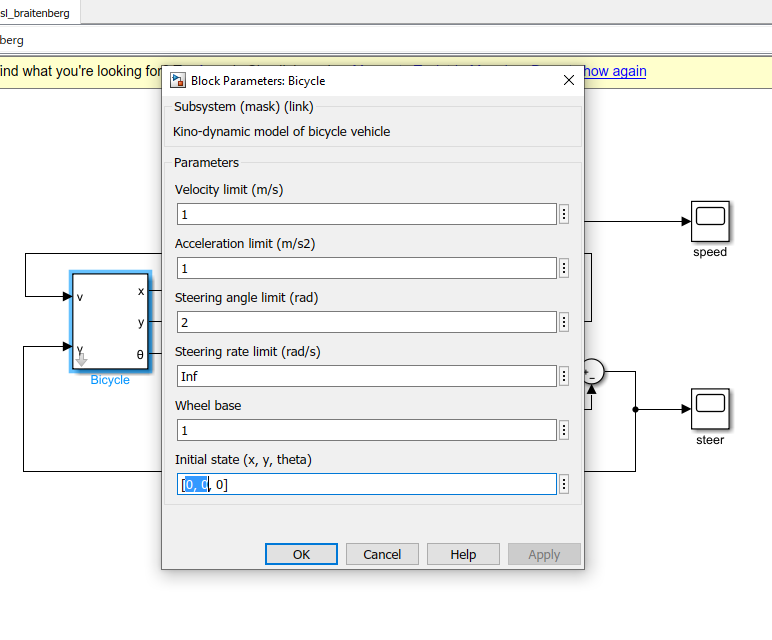

Starting from  [0,0] we can see that the robot does a wide steer to achieve the light:

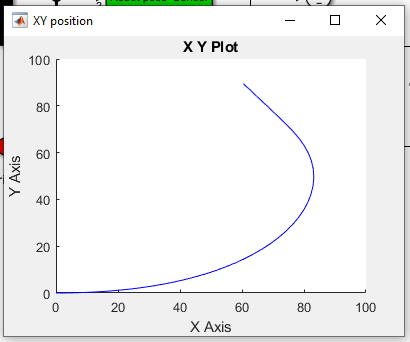

Starting from [30,30] we can see that the robot does a small steer to achieve the light:

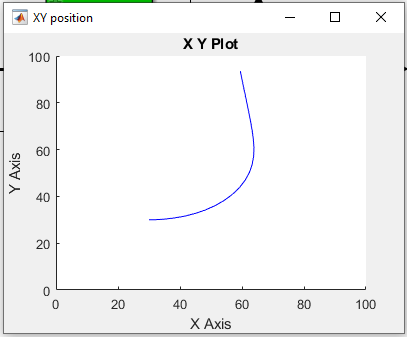

Starting from [50, 100] we can see that the robot starts near the light so it steers around the light:

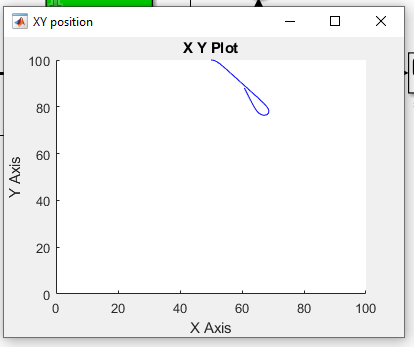

### Part B

%sl_braitenberg

To change the steering we need to change the signals on the Robot Pose sensor. In this case we change from -2 to 2 on the left sensor and viceversa on the right sensor:

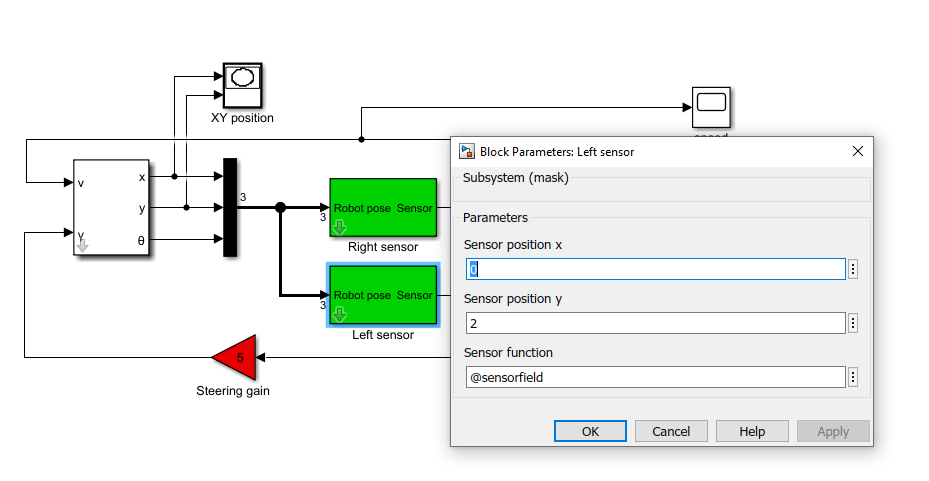

Starting from pos 0,0 and making the grid wider we can see that the robot runs away from the light:

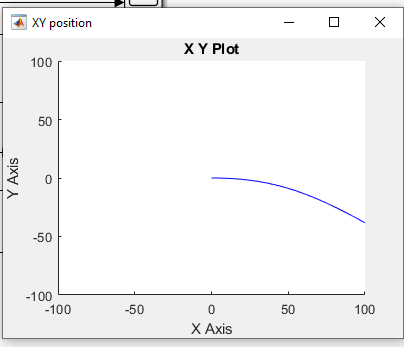

### Part C

%sl_braitenberg_1c

We added a clock to the 4th position of the bus so that the sensorfield function recieves the clock parameter:

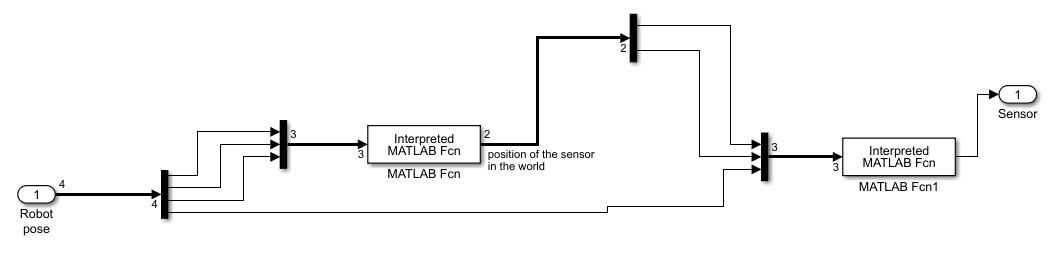

We used the parameter to modify the light position at each iteration:

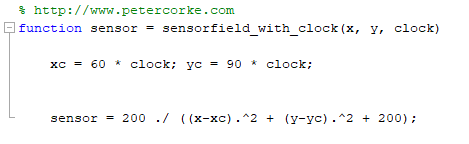

As you can see in the graphics, the robot follows the light without never arriving into it. The execution finishes due to the stop time marked to 200:

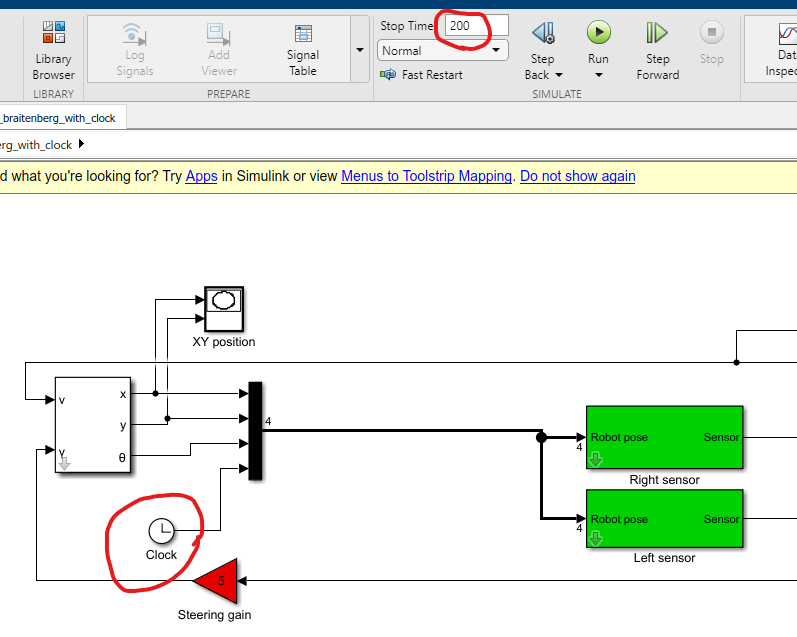

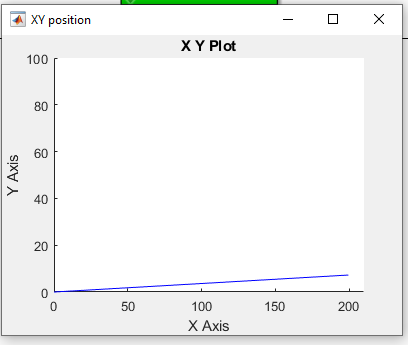

### Part D

%sl_braitenberg_1d

Note: We deactivated the clock behaviour for this section.

We added if else statment for every sensor output. If value is over 0.95, the program stops.

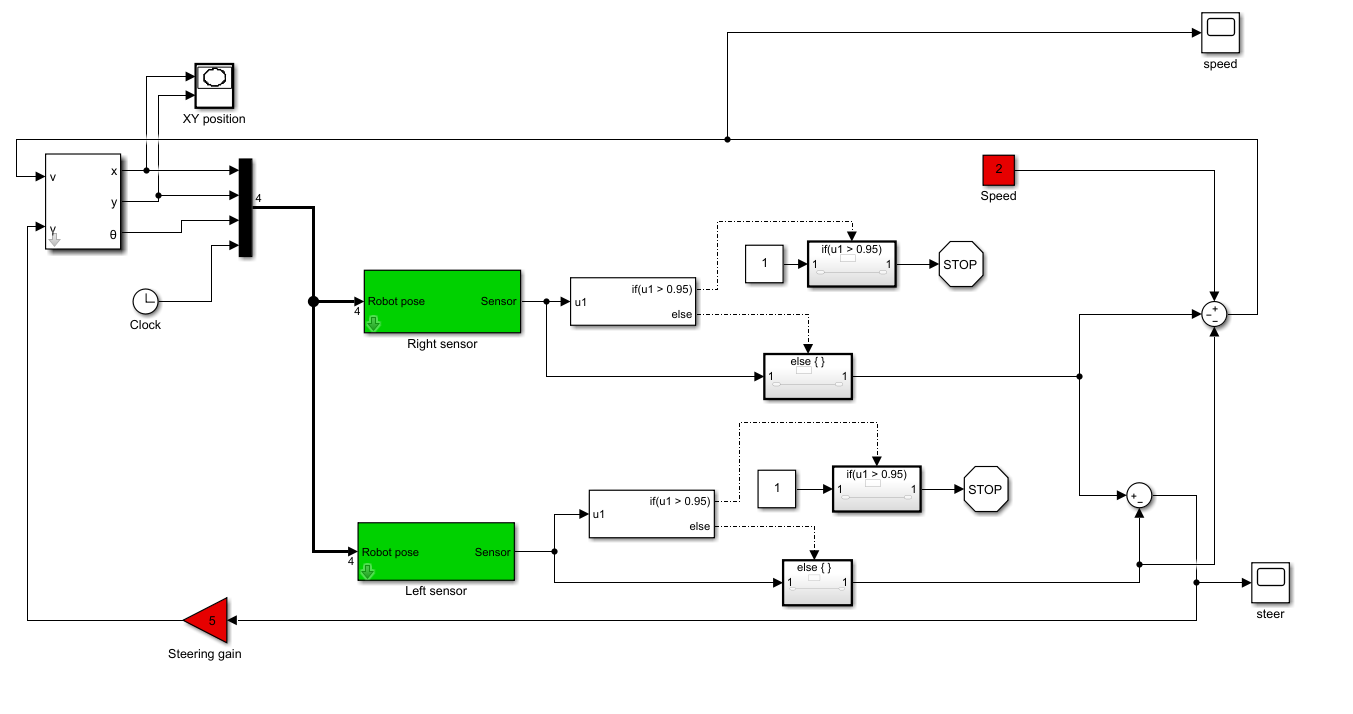

As we can see in the execution, the program stops almost on the light point, but before arriving to it. We added a grey line to observe easily the position difference:

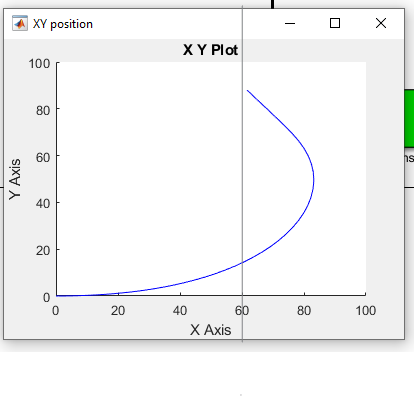

### Part E

%sl_braitenberg_1e

We created another sensor calculus for the right and left sensor with a new position. The max sensor output is the one that is being chosen.

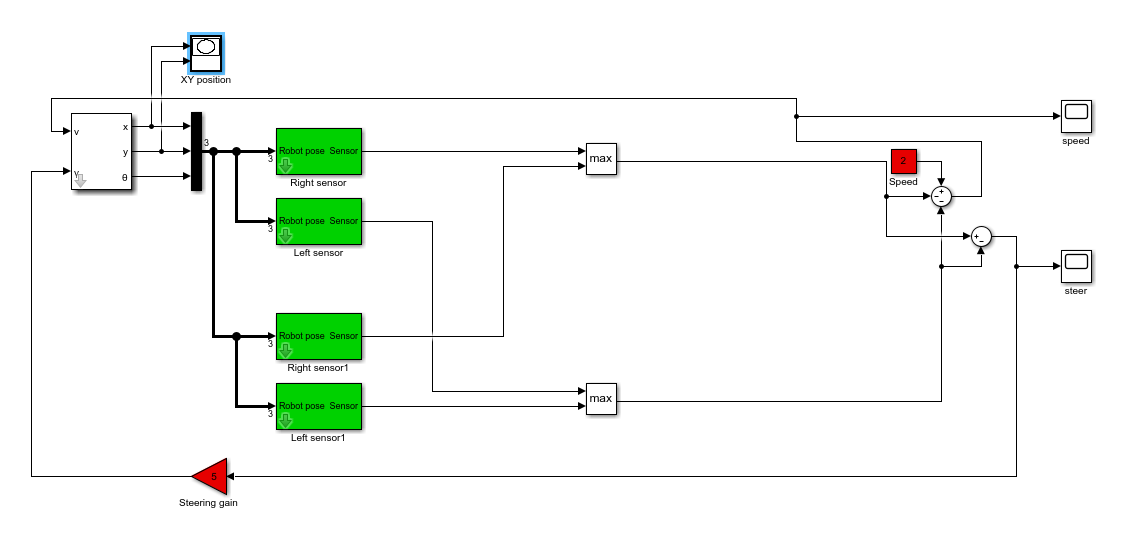

If the second position is [60,50], the robot leans toward this new position since its nearer than the original [60,90]:

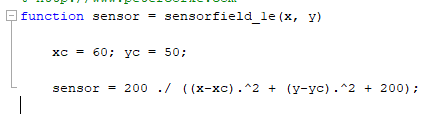

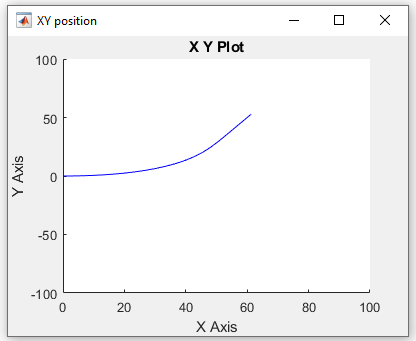

To confuse the robot, we can use equidistant positions so that the robot can't choose where to go. We will use [60, -90] as the second position:

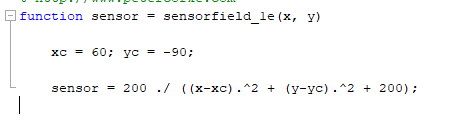

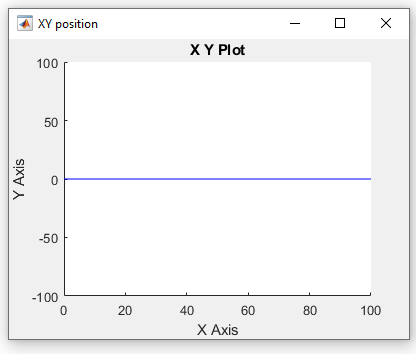

## Braitenberg modified

We modified the braitenbergh so that the behaviour can be modified internally:

%sl_braitenberg_mod

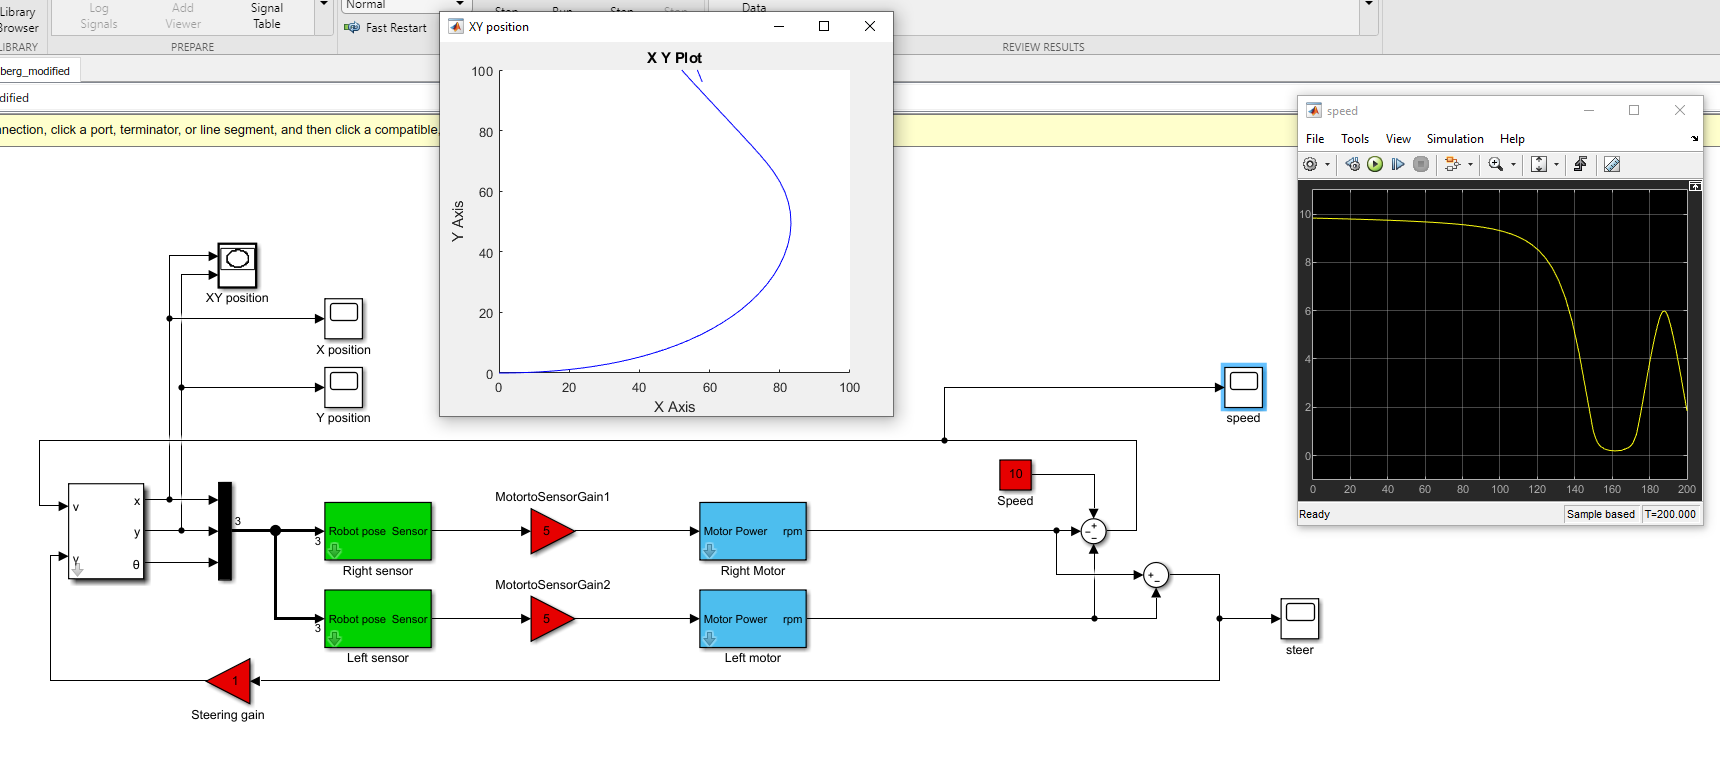

## Exercise 3

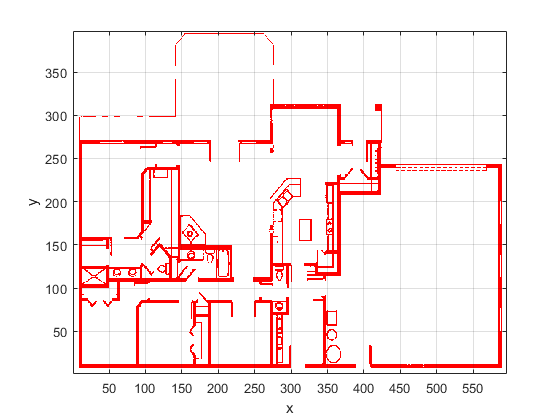

load house;

bug = Bug2(house);
bug.plot()

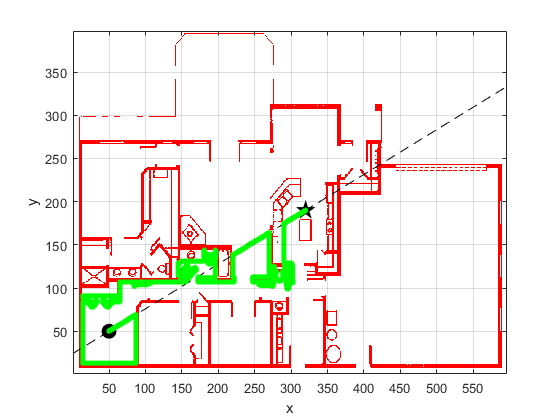


bug.query(place.br3, place.kitchen, 'animate');

### Part A

% map = makemap(100);
% save('3A.mat','map');

The map is loaded from a presaved .mat file:

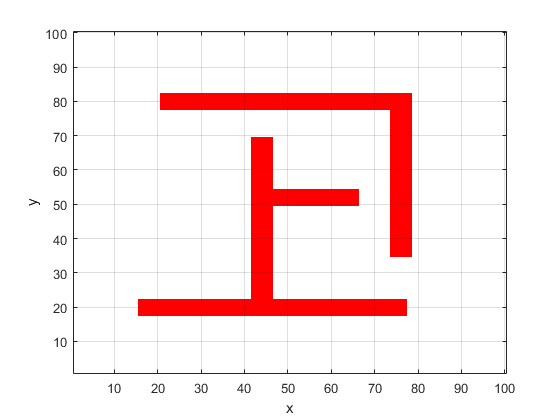

load('3A.mat');

bug = Bug2(map);
bug.plot()

We test the bug with 2 different starting points:

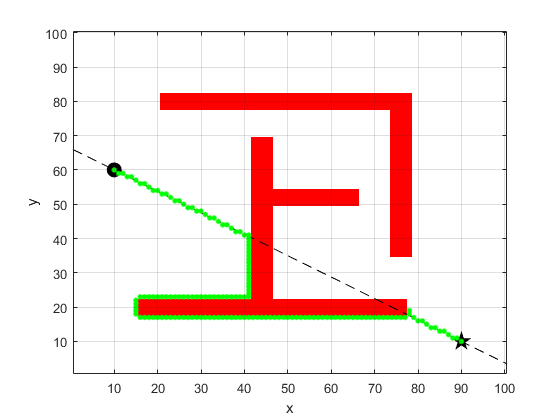

bug.query([10;60], [90;10], 'animate');

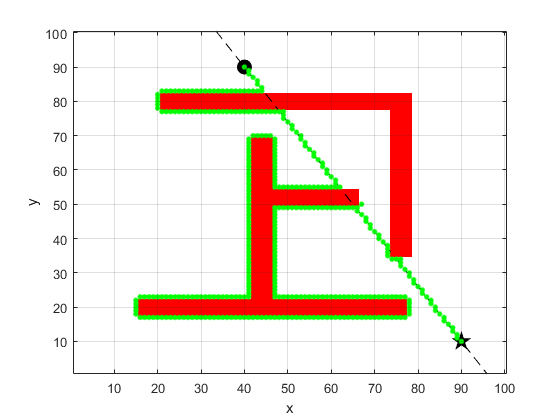

bug.query([40;90], [90;10], 'animate');

### Part B

% map = makemap(100);
% save('3B.mat','map');

The map is loaded from a presaved .mat file:

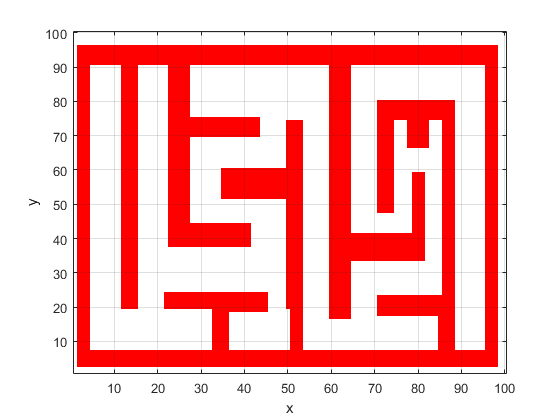

load('3B.mat');

bug = Bug2(map);
bug.plot()

We test the bug through all the maze:

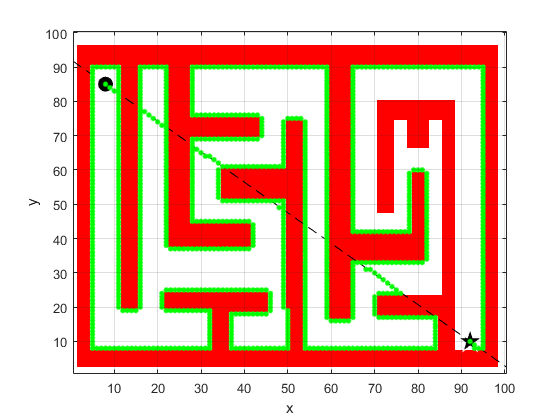

bug.query([8;85], [92;10], 'animate');

### Part C

The map is loaded from a presaved .mat file:

load('3B.mat');

bug = Bug2(map);
bug.plot()

We test the bug with other locations:

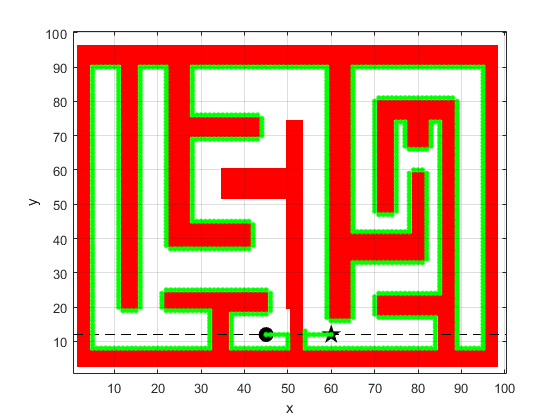

bug.query([45;12], [60;12], 'animate');

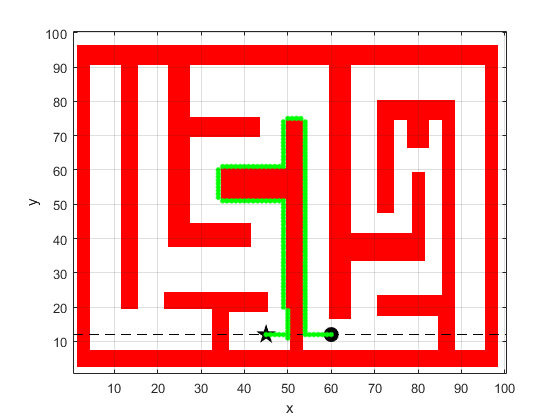

bug.query([60;12], [45;12], 'animate');

### Part D

% map = makemap(100);
% save('3D.mat','map');

The map is loaded from a presaved .mat file:

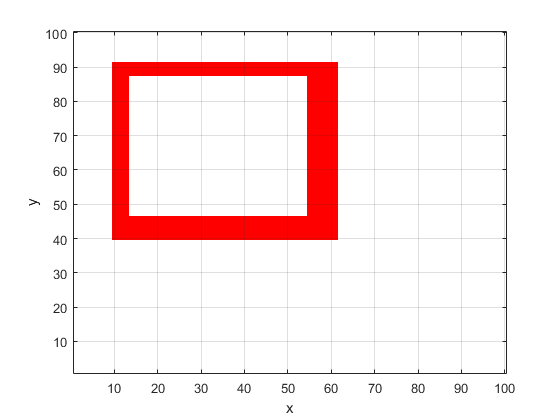

load('3D.mat');

bug = Bug2(map);
bug.plot()

Let's make the bug cry:

% bug.query([30;70], [45;15], 'animate');

% Line commented due to the error indicating that it is trapped.
% Uncomment in order to test the same output as the picture below.

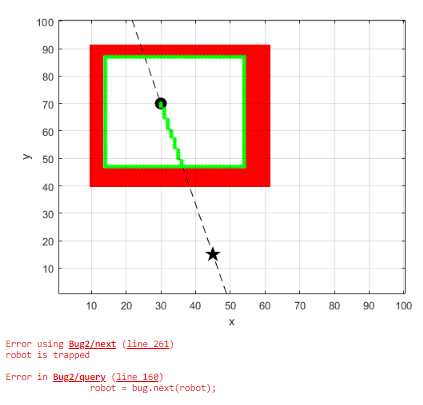

### Part E

We modified the Bug2 original code. The difference is that the next() method starts from last k and iterates to the first k available.

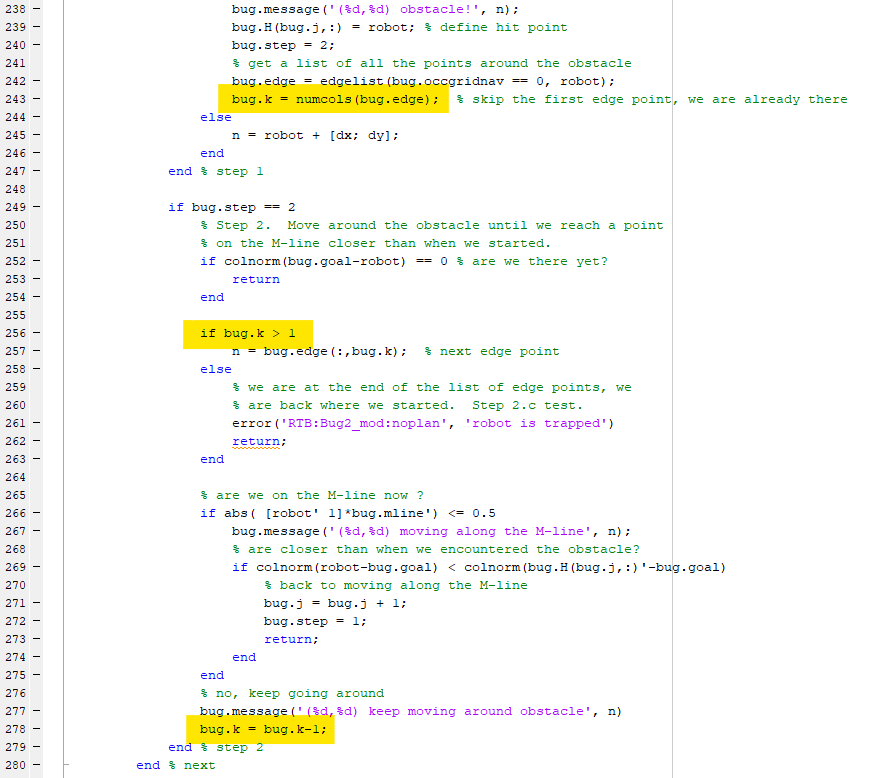

The map is loaded from a presaved .mat file:

load('3A.mat');

bug = Bug2_mod(map);
bug.plot()

We test the bug with 2 different starting points:

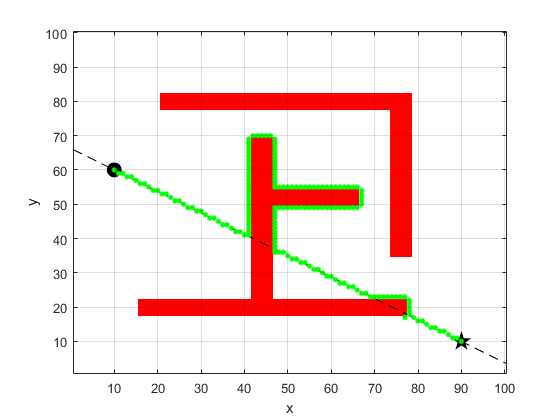

bug.query([10;60], [90;10], 'animate');

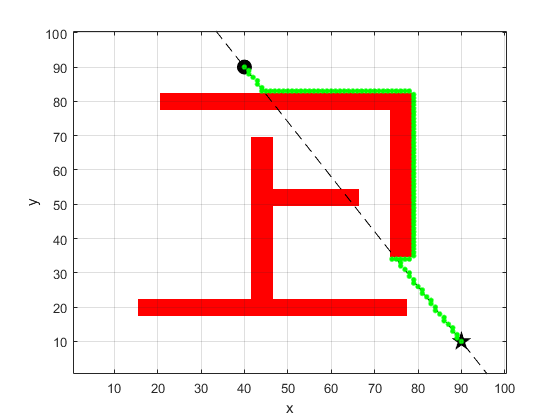

bug.query([40;90], [90;10], 'animate');